23 de febrero del 2022.

[GitHub](https://github.com/jdrengifoc/Stochastic-Process/)

# Taller de Seguimiento 1

Procesos estocásticos CM0433

**Nombre: ** Juan David Rengifo Castro.

**Código: **201810011101

## Problema

Considere el $Z_n = \{0,1,...,n-1\}$ el conjunto de clases residuales modulo $n$. Sobre este conjunto defina una cadena de Markov con la siguiente matriz de transición:


$$P\left(j,k\right)=\left\lbrace \begin{array}{cc}
0\ldotp 5 & \textrm{si}\;k\equiv j\pm 1\left(\textrm{mod}\;n\right),\\
0 & \textrm{en}\;\textrm{otro}\;\textrm{caso}\ldotp 
\end{array}\right.$$


### Análisis exploratorio

Para visualizar esta matriz de transición implementemos algunos casos a modo de ejemplo.

n = 16;
P = transition_matrix(n);
disp(sprintf("Matriz de transición de dimensión %d:", n))

Matriz de transición de dimensión 16:


P

P =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5000
    0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000         0    0.5000         0         0         0         0         0         0         0         0         0
         0         0         0

Resulta evidente que la matriz de transición es simétrica y todos los elementos que rodean su diagonal principal son positivos, en particular 0.5. Además, los extremos de la diagonal secundarias también son positivos. Para cualquier otro caso tenemos valores nulos. Pero esto implica que todos los elementos son accesibles desde cualquier elemento, por lo tanto, $P$ es **irreducible** para cualquier $n\geq3$. Para $n=1$ no es una matriz de transición pues su único elemento es $0.5\neq1$.

A continuación se muestra el **diagama de transición **para un $n$ arbitrario, donde cada flecha denota una probabilidad de transición de $0.5$.

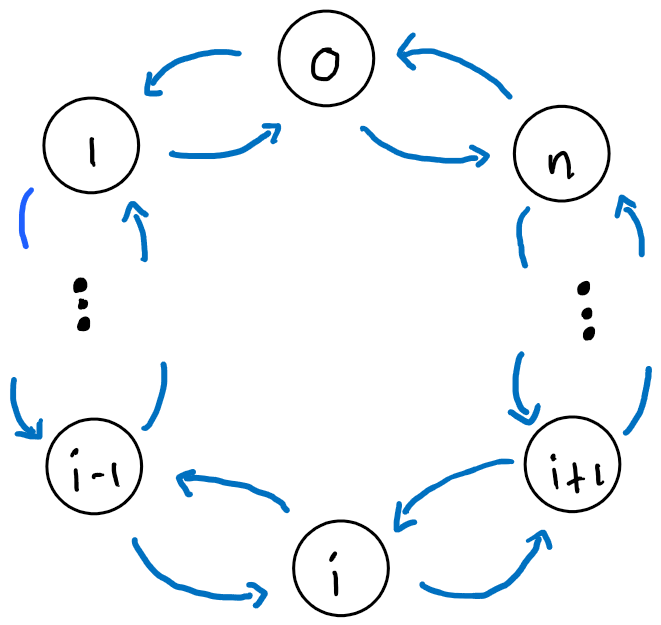

## **Problema 1**

¿Es un proceso recurrente aperiódico?

### Recurrencia

Sabemos que la recurrencia y la aperiodicidad de una cadena es una **propiedad de clase**, es decir, si un estado es recurrente y aperiodico, todos los estados que estén conectados con este (pertenezcan a la **clase de equivalencia**) también lo serán. Cabe resaltar, que si la cadena tiene una única clase de equivalencia, es decir, es **irreducible**, entonces existe una única clase de equivalencia y por tanto, que un estado tenga una propiedad de clase implica que la cadena tiene esta propiedad.

Antes de comenzar, recordemos que significan estas propiedades y como se definen.

La **recurrencia **se puede interpretar/definir de dos maneras:

- Dado que comencé en un estado, es* seguro que volveré. *Si el **tiempo esperado de retorno** del estado i $m_i$ es finitio, decimos que el estado i es **recurrente positivo**, de lo contrario, se dice que es **recurrente nulo**.

- El **número esperado de visitas** de un estado es infinito.

### Periodicidad

Por su parte, la **periodicidad **hace referencia al **periodo **de un estado. Un estado $i$ tiene periodo $d$ si:


$$d:=\textrm{mcd}\left\lbrace n:p_{\textrm{ii}}^n >0\right\rbrace$$


- Si $d=1$, entonces el estado es **aperiódico**.

- Si $d>1$, entonces el estado es **periódico**.

### **Solución**

gracias a nuestro análisis exploratorio, sabemos que la cadena de markov es **irreducible**, por lo tanto basta verificar para un único estado. Sin perder generalidad, sea $i$ un estado arbitrario.

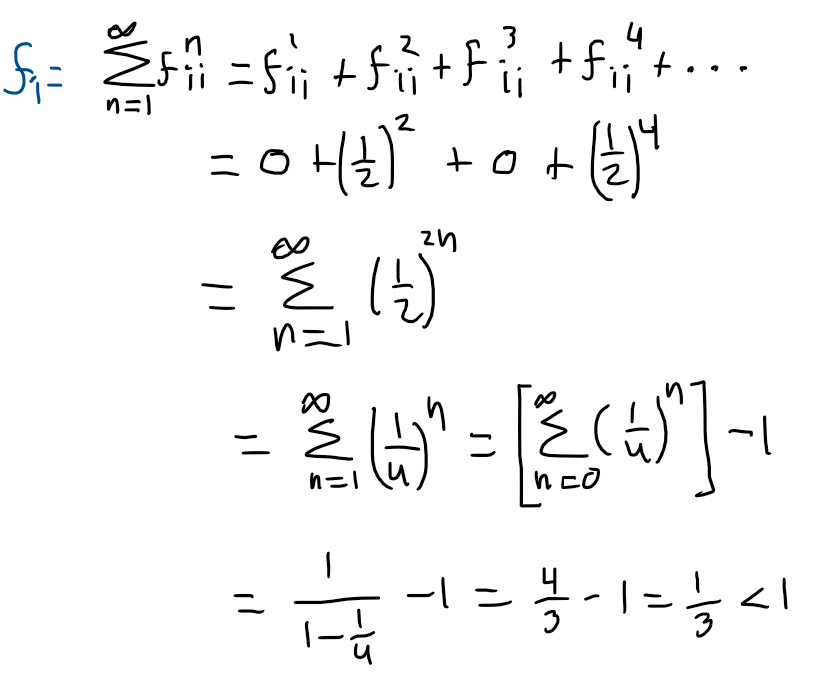

Por lo tanto, la cadena es **transitoria**, pues la probabilidad de comenzar en el estado $i$ y volver $f_i$ es menor a 1.

Por otra parte, como $p_{\textrm{ii}}^1 =0$, entonces $1\not\in \left\lbrace n:p_{\textrm{ii}}^n >0\right\rbrace$y así $d >1$, por lo que la cadena es **periódica**.

## **Problema 2**

Defina la versión perezosa del proceso, es decir, defina un proceso sobre el mismo espacio de estados pero que tenga una probabilidad de $1/4$ de avanzar, $1/4$ de retroceder y $1/2$ de quedarse en la misma posición. 

- ¿La versión perezosa del proceso es recurrente y aperiódica?

- ¿Cual es su medida estacionaria?

### **Solución**

Sea $P^*$ la matriz de transición original y $P$ la matriz de transición de la verisón perezosa,


$$P=\frac{1}{2\;}\left(I+P^* \right)$$


A continuación se muestra la matriz de transición para diferentes valores de $n$, notese que esta definición solo es válida para $n>3$, pues en otro caso cada fila no suma 1.

n = 3;
P = lazy_transition_matrix(n);
disp(sprintf("Matriz de transición de dimensión %d de la versión perezosa:", n))

Matriz de transición de dimensión 3 de la versión perezosa:


P

P =     0.5000    0.2500    0.2500
    0.2500    0.5000    0.2500
    0.2500    0.2500    0.5000


Así las cosas, tenemos el siguiente diagrama de transición,

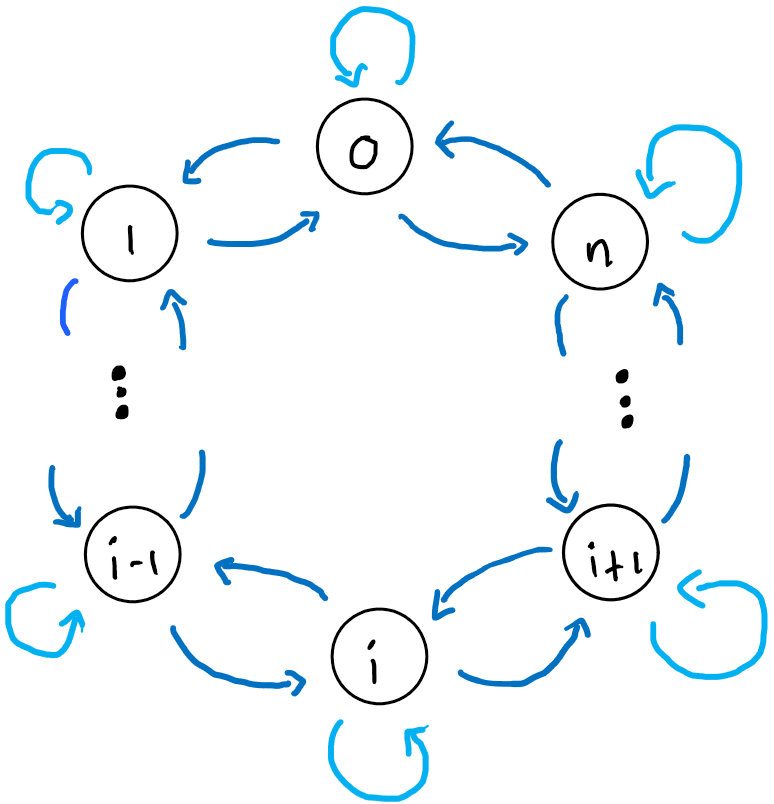

donde las flechas azul cian tienen probabilidad $1/2$ y las azules rey $1/4$.

Debe ser trivial para el lector, que de nuevo estamos ante una cadena **irreducible **y como el estado $0$ tiene un *loop* asì mismo, entonce $0$ tiene periodo 1, es decir, es **aperiódico **y por tanto la cadena también**.** Veamos este hecho de manera más formal, dado que $\forall i \in Z_n$, $P_{ii}^1 = 0.5 > 0$, entonces $1\in \left\lbrace n:p_{\textrm{ii}}^n >0\right\rbrace$. Asì $d=1$ y por tanto todos los estados son aperiódicos al igual que la cadena.

No obstante, la versión perezosa de la cadena sigue siendo **transitoria**, pues para un estado $i \in Z_n$, la probabilidad de comenzar en $i$ y volver a $i$ es menor a $1$, tal y como se muestra a continuación:

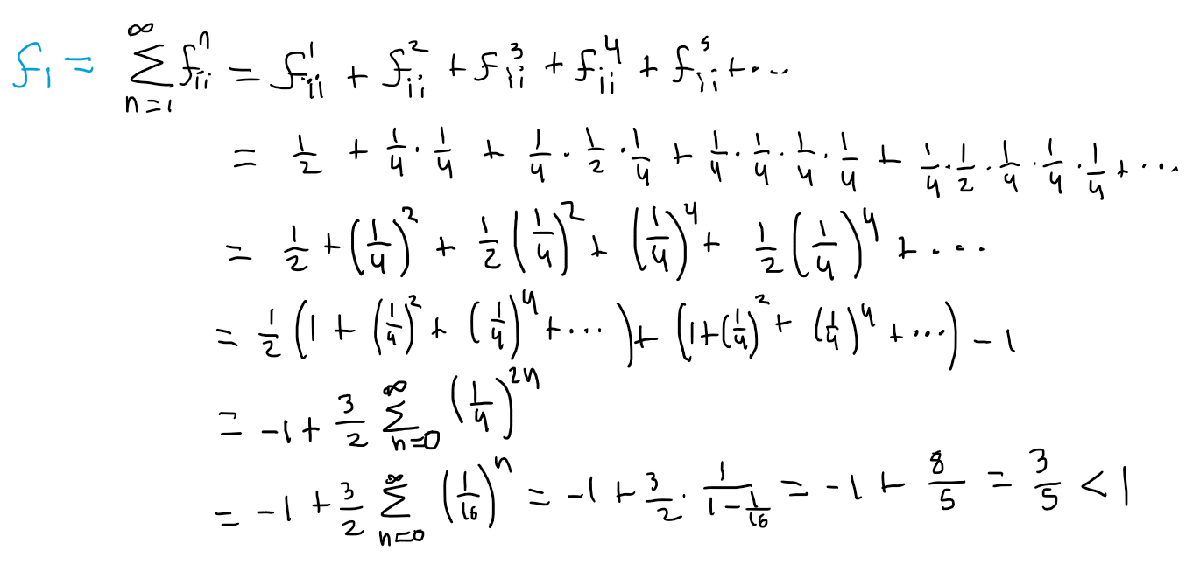

Para el numeral (2), sabemos que un vector $\Pi$ es una **medida estacionaria**, si suma $1$ y satisface $\Pi P = \Pi$.

Tenemos que


$$\mathrm{P}=\frac{1}{4}\left\lbrack \begin{array}{ccccc}
2 & 1 & 0 & 0 & 1\\
1 & 2 & 1 & 0 & 0\\
0 & 1 & \ddots  & 1 & 0\\
0 & 0 & 1 & 2 & 1\\
1 & 0 & 0 & 1 & 2
\end{array}\right\rbrack =\frac{{\mathrm{P}}^* }{4}$$


y sea $\Pi = [\pi_0, ..., \pi_{n-1}]$, resolvamos el sistema de ecuaciones $\Pi P = \Pi$. 


$$\Pi \mathrm{P}=\Pi$$



$$\Pi \left(\mathrm{P}-\mathrm{I}\right)=0$$



$$\frac{1}{4}\Pi \left(P-4I\right)=0$$



$$\Pi \left(P-4I\right)=0$$



$$\Pi \left\lbrack \begin{array}{ccccccc}
-2 & 1 & 0 & \cdots  & 0 & 0 & 1\\
1 & -2 & 1 & \cdots  & 0 & 0 & 0\\
0 & 1 & -2 & \cdots  & 0 & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & -2 & 1 & 0\\
0 & 0 & 0 & \cdots  & 1 & -2 & 1\\
1 & 0 & 0 & \cdots  & 0 & 1 & -2
\end{array}\right\rbrack =0$$


Resolviendo este sistema de ecuaciones de $n$ ecuaciones y $n$ incognitas, obtenemos que $\pi_0 =\cdots =\pi_{n-1} =k\in \mathrm{R}$. Pero para que sea **medida estacionaria** debe sumar $1$, por lo tanto 


$$\sum_{i=0}^{n-1} \pi_i =\sum_{i=1}^n k=nk=1$$



$$\;k=\frac{1}{n}$$


Por lo tanto, la media estacionaria de esta cadena es $\Pi = \frac{1}{n}[1, ..., 1]$.

Validamos esta solución por simulación y observamos que cuando $n\longrightarrow \infty$ para todo elemento $i$ del espacio de estado, $P^n \left(i,j\right)\longrightarrow \Pi \left(j\right)$.

n = 3;
steps = 4;
P = lazy_transition_matrix(n);
P_steps = steps_tm(P, steps);
Pi = 1/n*ones(1,n);

disp("Medida estacionaria")

Medida estacionaria


disp(Pi)

    0.3333    0.3333    0.3333



disp(sprintf("Matriz de transiciòn a %d pasos", steps))

Matriz de transiciòn a 4 pasos


disp(P_steps)

    0.3359    0.3320    0.3320
    0.3320    0.3359    0.3320
    0.3320    0.3320    0.3359



## **Problema 3**

Tomando en cuenta la versión no perezosa del proceso, defina $\tau_{cub}$ como el primer instante que el paseo aleatorio visita todos los estados. Utilice simulación para mostrar que el tiempo esperado de cubrimiento es $n(n-1)/2$, es decir,


$$\underset{x\in Z_n }{\textrm{máx}} \;E\left(\tau_{\textrm{cub}} \right)=\frac{n\left(n-1\right)}{2}$$


### Análisis de estabilidad

Aquí podemos analizar que aproximadamente después de 1200 simulaciones para $n$ entre $3$ y $20$, la media acumulada se estabiliza en el valor real  $\frac{n\left(n-1\right)}{2}$. Claramente, esto puede variar dependiendo de la semilla de pseudo-aleatorios y nivel de exactitud que se requiera.

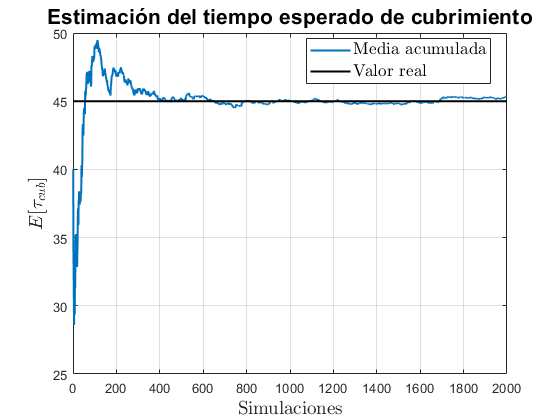

n = 10; 
nsim = 2000;
P = transition_matrix(n);
Tao = zeros(length(nsim), 1);

for i = 1:nsim
    Tao(i) = all_visited(n, P);
end

cummean = cumsum(Tao)./(1:nsim);
plot(1:nsim, cummean, ...
    1:nsim, ones(1,nsim)*n*(n-1)/2, 'k', 'LineWidth', 1.5);

title('Estimación del tiempo esperado de cubrimiento', 'FontSize', 16)
legend('Media acumulada', 'Valor real', ...
    'Location', 'best',  'Interpreter','latex', 'FontSize', 13)
xlabel('Simulaciones', 'Interpreter','latex','FontSize', 14)
ylabel('$E[\tau_{cub}]$', 'Interpreter','latex', 'FontSize', 14)
grid on

### Comprobación por simulación

Simulando observamos que el tiempo esperado de cubrimiento converge a $\frac{n\left(n-1\right)}{2}$ (*real*).

% Simulation parameters.
nsim = 10000;
nmax = 20;
N = 3:nmax;

% Preallocation.
mean_tao = zeros(1, length(N));

% For each n.
for n = N
    P = transition_matrix(n);
    % Preallocate vector of tao.
    Tao = zeros(n,1);
    
    % Simulate the time to cover all nsim times.
    for i = 1:nsim
        Tao(i) = all_visited(n, P);
    end
    mean_tao(find(n==N)) = mean(Tao);
end

% Results.
N = [1:2, N]; mean_tao = [nan, nan, mean_tao];
colNames = {'n', 'Real', 'Simulated'};
results = table(N', N'.*(N'-1)/2, mean_tao', 'VariableNames', colNames);

disp(sprintf("Resultados para %d simulaciones", nsim))

Resultados para 10000 simulaciones


disp(results)

    n     Real    Simulated
    __    ____    _________

     1      0         NaN  
     2      1         NaN  
     3      3      3.0135  
     4      6      6.0112  
     5     10      9.9525  
     6     15      14.977  
     7     21      21.039  
     8     28      27.847  
     9     36      36.245  
    10     45      45.284  
    11     55      55.446  
    12     66       66.08  
    13     78      77.778  
    14     91      90.972  
    15    105      104.64  
    16    120      120.66  
    17    136      135.87  
    18    153      154.12  
    19    171         171  
    20    190      189.62  



## **Problema 4**

Muestre el resultado anterior utilizando la siguiente estrategia. Considere $T_n$ el tiempo esperado que la cadena alcanza los $n$ estados. En el momento justo cuando la cadena a visitado $n-1$ estados distintos, los estados visitados se pueden disponer en una recta, uno tras otro y pensar el problema como la ruina del jugador. Así, podríamos tener $T_n = T_{n-1} + A_{n-1}$, donde $A_{n-1}$ es el tiempo esperado en alcanzar el estado $1$ (o $n-1$) en la ruina de un jugador.

**Solución.**

Sean $p_b$ y $p_f$ las probabilidades de retroceder y avanzar respectivamente, la **matriz de transición** general para la *ruina del jugador* será.

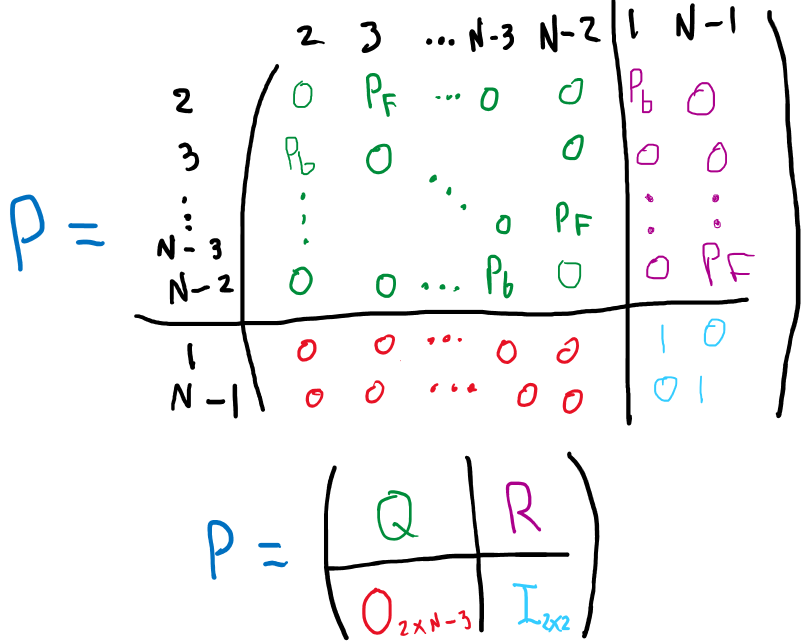

Para nuestro caso particular, tenemos que $P_b = P_f = 0.5%$ y tenemos el siguiente diagrama de transición, donde las flechas azules tiene probailidad $0.5$ y las rojas $1$.

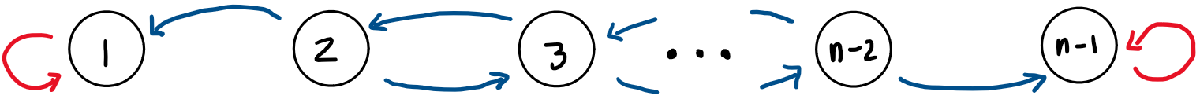

Reformulando la matriz de transición como una matriz bloque, sabemos que el elemento $i$ del vector

es el tiempo esperado de absobción desde el estado $i$. Para nuestro problema solo nos interesa el último elemento de $A_{n-1}$ pues entramos a la cadena asociada a $n-1$ cuando hemos visitado $n-2$ estados, es decir, comenzamos en el estado $n-2$. Denotemos este último elemento como $a_{n-1}$.

Es evidente que $T_0 = 0$, $a_1 = 1$ y $a_2 = 2$. Así las cosas, de manera recursiva hallamos $T_n$ en función de $a_i%$.


$$\begin{array}{l}
T_n =T_{n-1} +a_{n-1} \\
T_n =T_{n-2} +{a_{n-2} \;+\;a}_{n-1} \\
\;\;\;\;\;\vdots \\
T_n =T_1 +a_1 +a_2 +\cdots +a_{n-1} \\
T_n =\sum_{i=1}^{n-1} a_i 
\end{array}$$


nmax = 6;
p_ad = 0.5;

% Preallocate.
A = zeros(nmax-1,1);

% For each n. We don't count n == 1 since the process began with one state
% visited.
% With n indeed is n-1, since once we are absorb in n-1 we have visited n
% states.
for (n = 1:nmax-1)
    % Trivial
    if (n <= 2)
        A(n) = n;
    else
        % Transitory transition matrix.
        Q = transitories_gamblersruin(n, p_ad);
        % R = [1-p_ad, 0; zeros(n-2,2); 0, p_ad];
        I = eye(n);
        % The element i is the xpected time of absorbtion since state i.
        aux = inv(I-Q)*ones(n,1);
        % We came from visiting n-1 states.
        A(n) = aux(end);       
    end
    
end
% Results.
N = 1:nmax;
colNames = {'n', 'Real', 'ByGamblersRuin'};
results = table(N', N'.*(N'-1)/2, cumsum([0; A]), 'VariableNames', colNames);
disp(results)

    n    Real    ByGamblersRuin
    _    ____    ______________

    1      0            0      
    2      1            1      
    3      3            3      
    4      6            6      
    5     10           10      
    6     15           15      



## Funciones

% Transition matrix of non-lazy stochastic process.
function P = transition_matrix(n)
    P = reshape(1:n*n, n, n);
    for (i = 1:n*n)
        [j, k] = find(P==i);
        if (mod(j, n) == k-1 || mod(j-2, n) == k-1)
            P(j,k) = 0.5;
        else
            P(j,k) = 0;
        end
    end
end

% n steps transition matrix.
function P_steps = steps_tm(P, steps)
P_steps = P;
for i = 2:steps
    P_steps = P * P_steps;
end
end

% Transition matrix of lazy stochastic process.
function P = lazy_transition_matrix(n)
    P = reshape(1:n*n, n, n);
    for i = 1:n*n
        [j, k] = find(P==i);
        if (mod(j, n) == k-1 || mod(j-2, n) == k-1)
            P(j,k) = 0.25;
        elseif (j==k)
            P(j,k) = 0.5;
        else
            P(j,k) = 0;
        end
    end
end

% Simulation that returns the time until all the states are visited.
function tao = all_visited(n, P)
    % Not visited yet.
    toVisit = ones(1,n);
    % Initial state.
    pos = randi(n);
    % Cross out of the bucket list.
    toVisit(pos) = 0;
    % Update time.
    tao = 0;
    
    % While there are states to visit repeat the above.
    while any(toVisit)
       pos = find(rand() <= cumsum(P(pos,:)), 1);
       toVisit(pos) = 0;
       tao = tao + 1;
    end
end

% Transitory part of the transition matrix of the gambler's ruin.
function Q = transitories_gamblersruin (n, p)
    Q = reshape(1:n*n, n, n);
    for (i = 1:n*n)
        [j, k] = find(Q==i);
        if (mod(j, n) == k-1)
            Q(j,k) = p;
        elseif (mod(j-2, n) == k-1)
             Q(j,k) = 1-p;   
        else
            Q(j,k) = 0;
        end
    end
    Q(n,1) = 0; Q(1,n) = 0;
end
